% generate figure 7
% TBD: done by Devika

% dependence: initRSG2prior, v2struct, DnPlotResponses2P

### set up

S=initRSG2prior;
v2struct(S); % behDir

### main loop

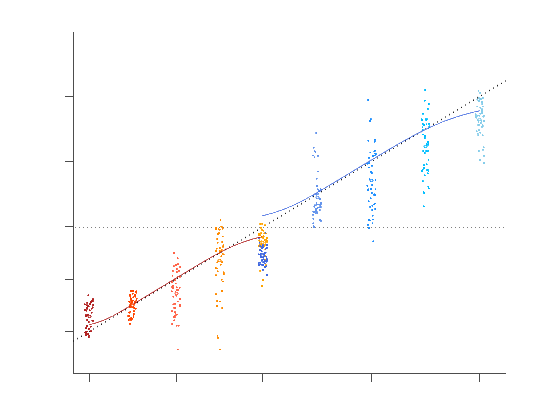

plot_tp_ts(S); % fig7B + insets


plot_trajectory_RNN(S); % fig7C

plot_compression(S); % fig7D

plot_translation(S); % fig7E



function plot_tp_ts(S) % fig7B + insets

v2struct(S);
load('traj_ts_Weber_2Prior_Type2_005_v5.mat');

ctidx=2-idShortTrial; % 1 for short, 2 for long
ipidx=nan(size(ctidx));
d.ts=ts;
d.tp=tp;

% data formatting: [# interval x maxRepetition]
% find max # trials 1st
for i=1:nPr
    for k=1:nTspp
        id=idShortTrial==(2-i) &... % idShortTrial
            ts==Tmat{i}(k); % ts
        if exist('nMaxTrial')
            nMaxTrial=max([nMaxTrial; nnz(id)]);
        else
            nMaxTrial=nnz(id);
        end
        ipidx(id)=k; % for each trial in d.ts specifies which time bin or ts interval it belongs to. Values: 1-5
    end
end
% filling matrix
Ts=nan(length(Tall),nMaxTrial); % [K x R]
Tp=nan(length(Tall),nMaxTrial);
for i=1:nPr
    for k=1:nTspp
        id=idShortTrial==(2-i) &... % idShortTrial
            ts==Tmat{i}(k); % ts
        Ts((i-1)*nTspp+k,1:nnz(id))=ts(id);
        Tp((i-1)*nTspp+k,1:nnz(id))=tp(id);
    end
end
d.Ts=Ts;
d.Tp=Tp;
% theory

    wm=.05; % wFit.w_m;
    wp=.05; % wFit.w_p;
    offset=[0;0]; % [wFit.offset2; wFit.offset1];

for i=1:nPr
    theory{i}.tm=[min(Tmat{i}):max(Tmat{i})]'; % theory{x}.tm - Tx1 - sample corresponding to above
    theory{i}.te=BLS(theory{i}.tm,wm,[min(Tmat{i}) max(Tmat{i})],'uniform')+offset(i);theory{i}.te=theory{i}.te(:);
    theory{i}.range=1:length(theory{i}.tm);
    theory{i}.wm=wm;
end
DnPlotResponses2P(d,theory,ctidx,ipidx);

% paper
% set(gca,'xtick',400:400:1200,'ytick',400:400:1200,'ylim',[300 1450]); 
xlim([450 1250]);
set(gca,'xtick',[480 640 800 1000 1200],'ytick',[480 640 800 1000 1200],'xticklabel',[],'yticklabel',[]);
ylim([350 1400]);
xlabel([]);ylabel([]);
title([])

end

function plot_trajectory_RNN(S) % fig7C

end

function plot_compression(S) % fig7D

end

function plot_translation(S) % fig7E

end